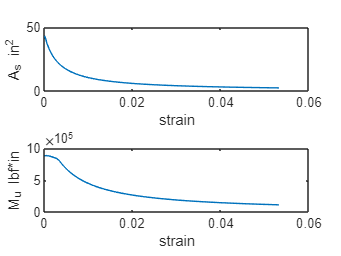

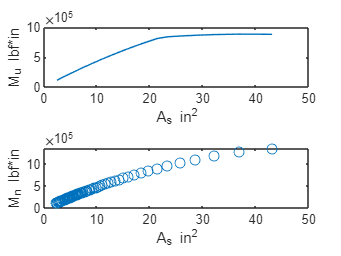

% Definition

f_c = 2500; % Concrete Compressive Strength (psi)
f_y = 5000; % Reinforcement Yield Strength (psi)
E_s = 29000*1000; % Reinforcement Elastic Modulus (psi)

b = 12; % Cross Section Width (in)
d = 10.5; % Effective Cross Section Depth (in)

strain_cu = -0.003; % Concrete Extreme Compressive Strain
strain_ty = f_y/E_s; % Reinforcement Yield Strain 

Array_strain_t = linspace(strain_ty, strain_ty+0.053);

Flexural_Strength_Design(Array_strain_t, f_c, f_y, b, d, strain_cu, strain_ty)


9.3e+5/12000

ans = 77.5000

function Flexural_Strength_Design(Array_strain_t, f_c, f_y, b, d, strain_cu, strain_ty) % Flexural Strength Design
    n = size(Array_strain_t, 2);
    Array_A_s = zeros(1,n);
    Array_M_n = zeros(1,n);
    Array_M_u = zeros(1,n);

    Beta_1 = Find_Beta_1(f_c);

    for i = 1:n
        strain_t = Array_strain_t(i);

        % A_s = 0.85*f_c*b/f_y*Beta_1 * strain_cu/(strain_cu-strain_t) * d;
        % M_n = f_y * A_s * ( d - Beta_1/2 * strain_cu/(strain_cu-strain_t) * d );
        Array_A_s(i) = 0.85*f_c*b/f_y*Beta_1 * strain_cu/(strain_cu-strain_t) * d;
        Array_M_n(i) = f_y * Array_A_s(i) * ( d - Beta_1/2 * strain_cu/(strain_cu-strain_t) * d );
        
        Phi = Find_Phi(strain_t, strain_ty);
        Array_M_u(i) = Phi * Array_M_n(i);
    end
    figure
    subplot(2,1,1);
    plot(Array_strain_t, Array_A_s)
    xlabel('strain')
    ylabel('A_s in^2')

    subplot(2,1,2); 
    plot(Array_strain_t, Array_M_u)
    xlabel('strain')
    ylabel('M_u lbf*in')

    figure
    subplot(2,1,1); 
    plot(Array_A_s, Array_M_u)
    xlabel('A_s in^2')
    ylabel('M_u lbf*in')

    subplot(2,1,2); 
    plot(Array_A_s, Array_M_n, 'o')
    xlabel('A_s in^2')
    ylabel('M_n lbf*in')

end
    
function Beta_1 = Find_Beta_1(f_c) % Compression Zone Factor
    if f_c >= 2500 && f_c <= 4000
        Beta_1 = 0.85;
    elseif f_c < 8000
        Beta_1 = 0.85-0.05*(f_c-4000)/1000;
    else
        Beta_1 = 0.65;
    end
end

function Phi = Find_Phi(strain_t, strain_ty) % Flexural Strength Reduction Factor
    if strain_t <= strain_ty
        Phi = 0.65;
    elseif strain_t < strain_ty + 0.003
        Phi = 0.65+0.25*(strain_t-strain_ty)/0.003;
    else
        Phi = 0.9;
    end
end